clear all

% Model Parameters (extracted from Table S1 in SI)
% ====================================================
%                  [Unit]   Variable definition
% ====================================================
n_m = 75;          %          Number of myosin motors
F_m = -2;          % [pN]     Single myosin motor stall force
v_u = -120;        % [nm/s]   Unloaded myosin motor velocity
n_c = 75;          %          Number of molecular clutches
k_on = 1;          % [s^(-1)] Rate of clutch binding
k_off = 0.1;       % [s^(-1)] Rate of clutch unbinding
F_b = -2;      % [pN]     Characteristic bond rupture force
k_clutch = 5;      % [pN/nm]  Molecular clutch spring constant

% Running Variables
% =======================
events_simulated = 1e5;
v_filaments_t = zeros(1, events_simulated);
dts = zeros(1, events_simulated);
k_substrate = 1;
cell_areas = 0.5:0.05:2; % Relative cell area
average_vs = zeros(1, length(cell_areas));

% Varying the cell area and seeing the effects on cell velocity
tic
i = 1;
for cell_area = cell_areas
    x_substrate = 0;
    t = 0;

    new_n_c = round(n_c * cell_area);

    x_clutches = zeros(1, new_n_c);
    clutch_states = zeros(1, new_n_c);

    for ii = 1:events_simulated
        % Calculate velocity of the F-actin
        v_filament = v_u * (1 - ((k_substrate * x_substrate) / (n_m * F_m)));

        % Calculate force on the clutches
        F_clutch = k_clutch * (x_clutches - x_substrate);
        
        % Use Gillepsie algorithm to simulate the next event
        [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
        
        % Change the state of the clutch
        clutch_states(state_idx) = is_bind;
        if ~is_bind
            x_clutches(state_idx) = x_substrate;
        end
        
        engaged_clutch_idx = find(clutch_states==1);
        disengaged_clutch_idx = find(clutch_states==0);
        
        % Find the position of the substrate
        x_substrate = (k_clutch * sum(x_clutches(engaged_clutch_idx))) / (k_substrate + (length(engaged_clutch_idx) * k_clutch));
        
        % Displace engaged clutches
        x_clutches(engaged_clutch_idx) = x_clutches(engaged_clutch_idx) + (v_filament * dt);
        
        % Set disengaged clutch displacement to the displacement of the
        % substrate
        x_clutches(disengaged_clutch_idx) = x_substrate;
        t = t + dt;
    
        v_filaments_t(ii) = v_filament;
        dts(ii) = dt;
    end
    average_vs(i) = sum(v_filaments_t .* dts) / sum(dts);
    i = i + 1;
end
toc

Elapsed time is 49.418844 seconds.


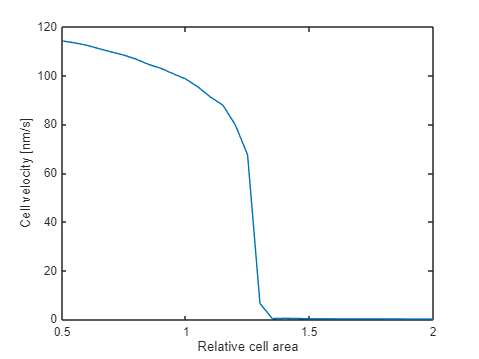

plot(cell_areas, -average_vs, '-');
xlabel("Relative cell area");
ylabel("Cell velocity [nm/s]");